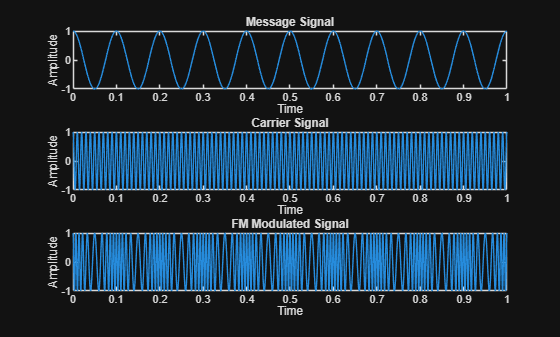

clc;
clear;
close all;

% Parameters
fs = 10000;          % Sampling frequency
t = 0:1/fs:1;        % Time vector

Am = 1;              % Message amplitude
fm = 10;             % Message frequency

Ac = 1;              % Carrier amplitude
fc = 100;            % Carrier frequency
kf = 50;             % Frequency sensitivity

% Message Signal
m = Am*cos(2*pi*fm*t);

% FM Modulated Signal
fm_signal = Ac*cos(2*pi*fc*t + 2*pi*kf*cumtrapz(t,m));

% Plot Time Domain Signals
figure;

subplot(3,1,1)
plot(t,m)
title('Message Signal')
xlabel('Time')
ylabel('Amplitude')

subplot(3,1,2)
carrier = Ac*cos(2*pi*fc*t);
plot(t,carrier)
title('Carrier Signal')
xlabel('Time')
ylabel('Amplitude')

subplot(3,1,3)
plot(t,fm_signal)
title('FM Modulated Signal')
xlabel('Time')
ylabel('Amplitude')

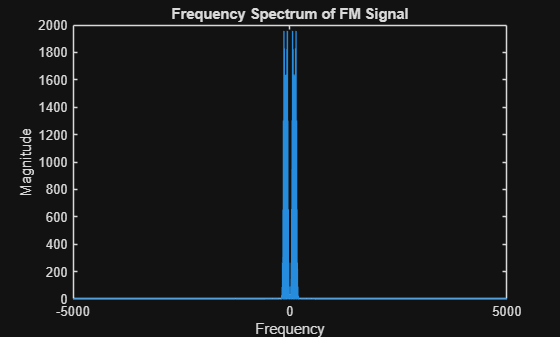

% FFT of FM signal
N = length(fm_signal);
f = (-N/2:N/2-1)*(fs/N);

FM_fft = fftshift(abs(fft(fm_signal)));

figure
plot(f,FM_fft)
title('Frequency Spectrum of FM Signal')
xlabel('Frequency')
ylabel('Magnitude')

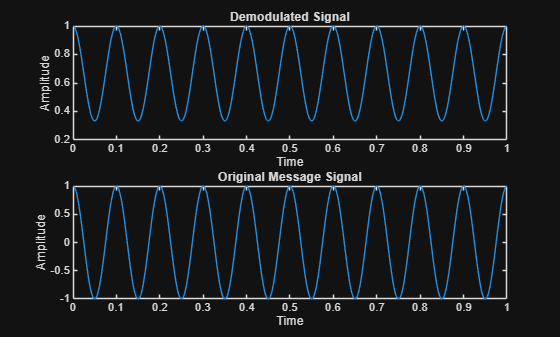

% Differentiate FM signal
diff_signal = diff(fm_signal);

% Envelope detection
demod = abs(hilbert(diff_signal));

% Normalize
demod = demod/max(demod);

figure

subplot(2,1,1)
plot(t(1:end-1),demod)
title('Demodulated Signal')
xlabel('Time')
ylabel('Amplitude')

subplot(2,1,2)
plot(t(1:end-1),m(1:end-1))
title('Original Message Signal')
xlabel('Time')
ylabel('Amplitude')

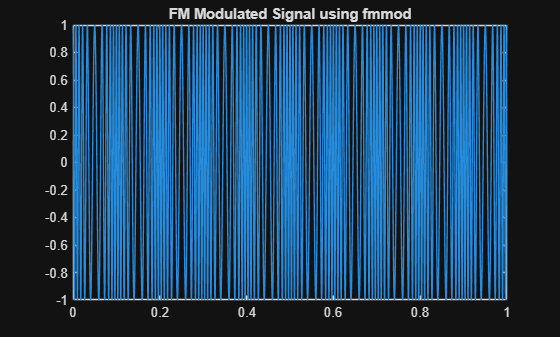

fs = 10000;
t = 0:1/fs:1;

fm = 10;
fc = 100;

m = cos(2*pi*fm*t);

fm_mod = fmmod(m,fc,fs,50);

figure
plot(t,fm_mod)
title('FM Modulated Signal using fmmod')

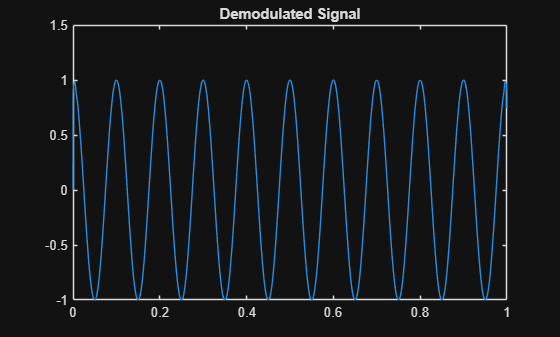

demod = fmdemod(fm_mod,fc,fs,50);

figure
plot(t,demod)
title('Demodulated Signal')